# Machine Learning Prediction of Side effects of Drugs in Clinical Trials

Diego Galeano, Alberto Paccanaro

clc;close all; clear all;
addpath('data\')
addpath('source\')

#### Read datasets


data = load('data/dataForExp.mat');

Data from clinical trials

Xct = double(data.Xct > 0);
[ndrugs, nses] = size(Xct);

Postmarketing data

X_postmarket_sider = data.Xpost > 0;
X_postmarket_offsides = data.Xoffs > 0;

#### Preprocessing 

Remove associations that are also found in clinical trials

% combine both post
X_postmarket_sider(Xct > 0) = 0;
X_postmarket_offsides(Xct > 0) = 0;

#### Build drug graph information 

GDrugs = cell(4,1); GSE = cell(1,1);

GDrugs{1} = 1 - squareform(pdist(data.DChemMACCS, 'jaccard'));
GDrugs{2} = 1 - squareform(pdist(data.DInd, 'Jaccard'));
GDrugs{3} = 1 - squareform(pdist(data.DTarget, 'Jaccard'));

ATC_hier_data = load('data/ShortestPathDrugsATCHierarchy.mat');
GDrugs{4} = 1- ATC_hier_data.TAX_SP./max(ATC_hier_data.TAX_SP);

% remove main diagonal
for i = 1:4   
    GDrugs{i} = GDrugs{i} - diag(diag(GDrugs{i}));
end

#### Build side effect graph information

d = load('data/ShortestPathSEMedDRAHierarchy.mat');
GSE{1} = 1- d.TAX_SP./max(d.TAX_SP);
GSE{1} = GSE{1} - diag(diag(GSE{1}));

#### GSEM model hyperparameters


maxiter = 500;

params = load('data/Metrics_GSEM_ALL.mat');
myl2_drugs = params.best_model_AUC_LEFT(1);
myl1_drugs = params.best_model_AUC_LEFT(2);
alpha_drugs = params.best_model_AUC_LEFT(3:end);
myl2_se = params.best_model_AUC_RIGHT(1);
myl1_se = params.best_model_AUC_RIGHT(2);
alpha_se = params.best_model_AUC_RIGHT(3);

#### Train GSEM on clinical trials data only to predict in postmarketing

[ W ] = GSEM( Xct', GDrugs, alpha_drugs, myl2_drugs, myl1_drugs); 


 iter: 21, dw = 9.266665e-03 


                            
    
[ H ] = GSEM( Xct, GSE, alpha_se, myl2_se, myl1_se);


 iter: 28, dw = 9.967574e-03 


    
Xhat = (Xct'*W)' + Xct*H; 

#### Evaluation

[result_GSEM, result_GSEM_binned] = performance_per_drug(Xhat,Xct, X_postmarket_sider, X_postmarket_offsides);
[auroc_per_ATC,...
    aupr_per_ATC,...
      auroc_per_MedDRA,...
        aupr_per_MedDRA] = performance_per_category(Xhat, Xct, X_postmarket_sider, X_postmarket_offsides, data.ATC{1}, data.MedDRA{1});

#### Visualization of performance per drug

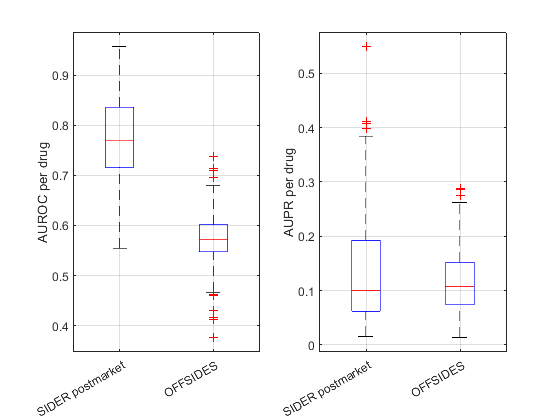

figure;
subplot(1,2,1)
boxplot([result_GSEM.auroc_sider'; result_GSEM.auroc_offs'], [ones(199,1); 2*ones(354,1)])
set(gca, 'XTickLabel', {'SIDER postmarket', 'OFFSIDES'})
ylabel('AUROC per drug')
grid on;

subplot(1,2,2)
boxplot([result_GSEM.aupr_sider'; result_GSEM.aupr_offs'], [ones(199,1); 2*ones(354,1)])
set(gca, 'XTickLabel', {'SIDER postmarket', 'OFFSIDES'})
ylabel('AUPR per drug')
grid on;

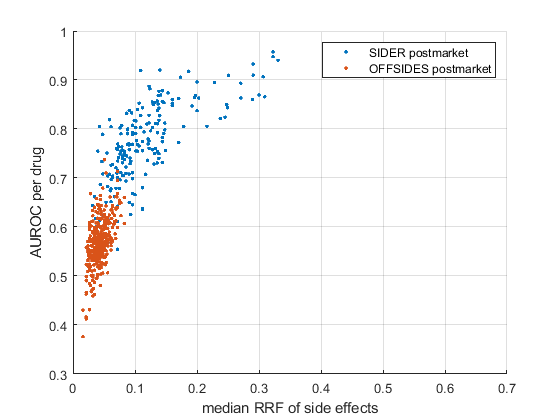

figure;
scatter(result_GSEM.rrf_sider, result_GSEM.auroc_sider,'.')
hold on;
scatter(result_GSEM.rrf_off, result_GSEM.auroc_offs,'.')
ylabel('AUROC per drug')
xlabel('median RRF of side effects');
legend({'SIDER postmarket', 'OFFSIDES postmarket'})
grid on;